folder = "11_04_22/catapult_data/*.csv";
files = dir(folder);
display(files)

files = 9×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file_num = 6; %start at 3
file = importdata(files(file_num).folder + "/" + files(file_num).name, ",");
data = file.data(file.data(:,1) < 2000000, :);

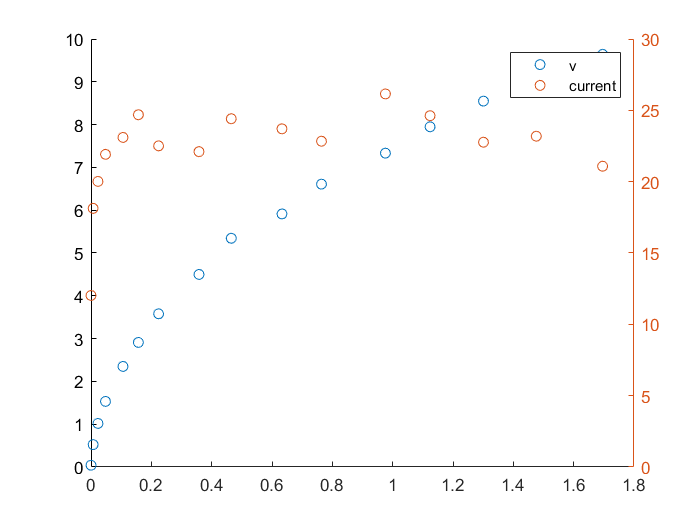

clf
hold on
scatter(data(:,1), data(:,2))
yyaxis right
scatter(data(:,1), -data(:,3))
ylim([0 30])
%scatter(data(:,1), data(:,4))
legend(["v", "current"])
hold off